Y = [0.444549667
0.360993112
0.617338217
1
0.236111282
0.833844549
0.186926317
0.583279014
0.689015046
0.493826462
0.4752874
0.721461479
0.001288084
0.258699896
0.20801367
0.119974648
0
0.00719966
0.26273715
0.25383781
0.136663986
0.045924169
0.030927953
0.446960212
0.446960212
0.299572579
0.344318533
0.209058239
0.152963864
0.335115825
0.658440476
0.359721426
0.07905687
0.387918248
0.564216028
0.225627869
0.262619082
];
x1 = [0.21
0.25
0.25
0.25
0.25
0.35
0.49
0.5
0.76
0.77
0.77
1.07
1.3
1.54
1.96
2.14
2.3
2.57
3.39
3.77
3.88
4.04
4.06
4.11
4.14
4.41
4.7
4.71
4.97
5.16
6.38
8.04
8.51
8.75
9.62
10.62
10.8
] ;
x1 = x1';
Y = Y';

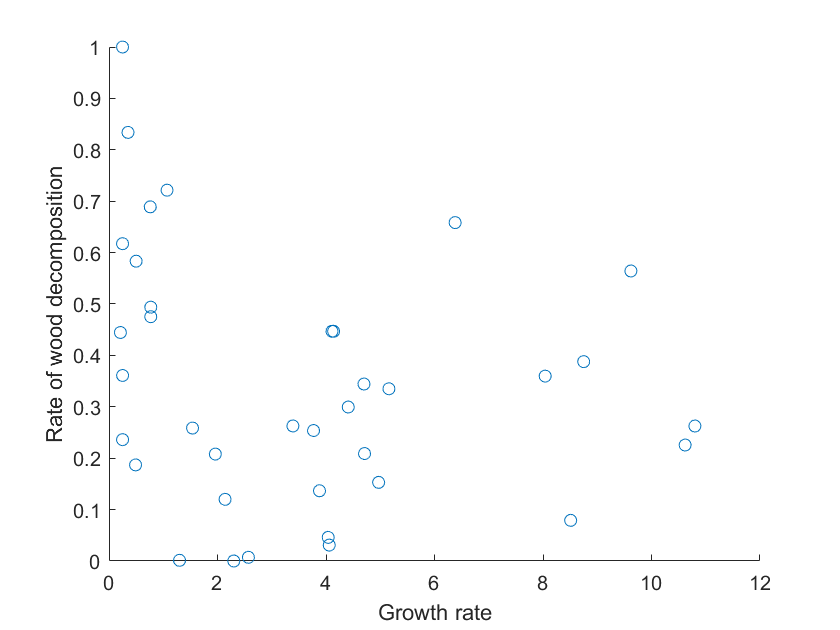

scatter(x1,Y);
xlabel('Growth rate');
ylabel('Rate of wood decomposition')

% hold on;
% Y2 = 0.050623*x1 + 3.183861*(-0.141482*(log(x1))+ 0.306328)-0.472609;
% plot(x1,Y2,'r')
% hold dff;

x_1 = [3.01
2.08
3.71
4.3
2.57
4.15
2.36
2.04
1.74
3.43
1.32
1.19
1.19
1.19
1.38
1.85
1.22
1.55
1.47
1.22
1.19
1.19
1.24
1.57
2.54
1.4
1.57
1.24
1.53
1.48
1.19
1.28
1.71
2.2
2.32
1.19
4.96
];
x_2 = [0.25
0.35
0.21
0.25
0.25
0.49
0.25
0.76
0.77
0.5
1.07
4.71
1.96
4.11
4.7
3.77
5.16
6.38
4.14
3.39
1.3
10.62
9.62
8.04
10.8
4.04
1.54
4.06
2.3
2.14
8.75
8.51
4.97
4.41
2.57
3.88
0.77
];



data = [x_1,x_2];



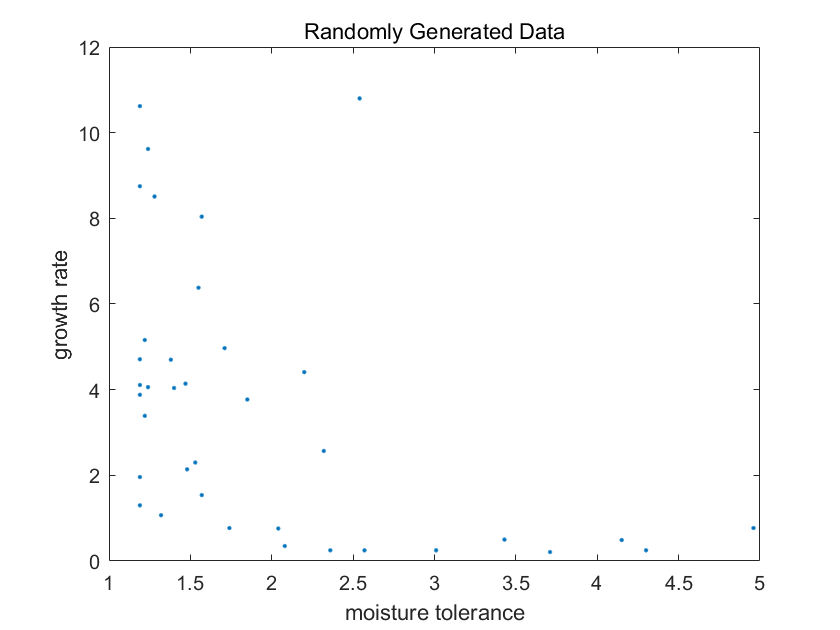


X=data;
[idx,C] = kmeans(X,2);
figure;
plot(X(:,1),X(:,2),'.');
xlabel('moisture tolerance');
ylabel('growth rate');
title 'Randomly Generated Data';

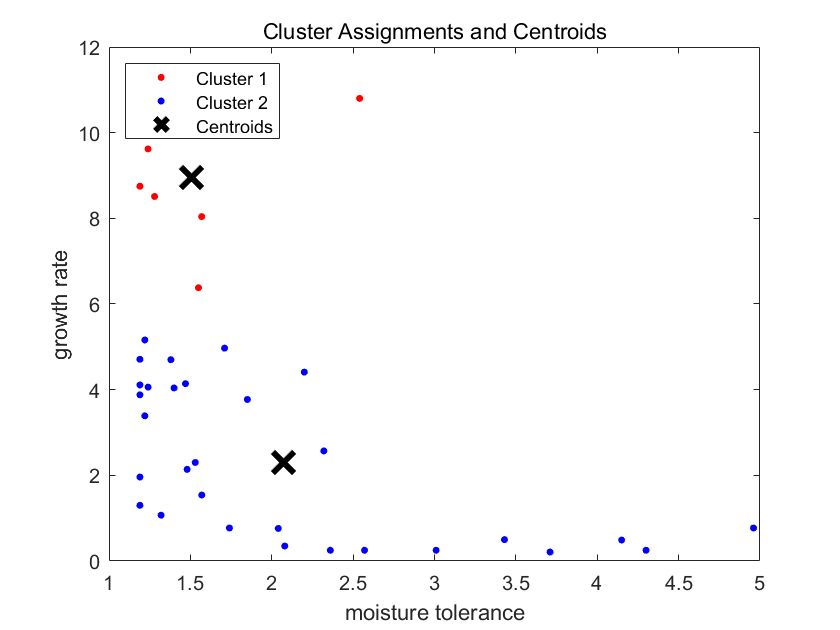

figure;
plot(X(idx==1,1),X(idx==1,2),'r.','MarkerSize',12)
hold on
plot(X(idx==2,1),X(idx==2,2),'b.','MarkerSize',12)
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3)
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
xlabel('moisture tolerance');
ylabel('growth rate');
hold off;

clear;
clc;
hold off;

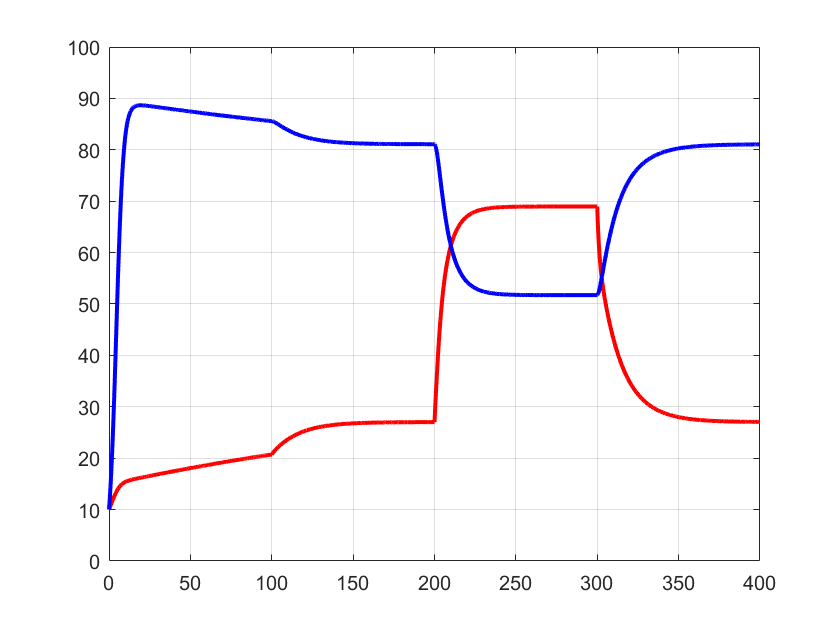


h=0.1;%所取时间点间隔
ts1=[0:h:100];%时间区间
x01=[10,10];%初始条件

opt=odeset('reltol',1e-6,'abstol',1e-9);%相对误差1e-6，绝对误差1e-9
[t1,x1]=ode45(@fun1,ts1,x01,opt);%使用5级4阶龙格—库塔公式计算

ts2=[100:h:200];%时间区间
x02=[x1(1001,1),x1(1001,2)];%初始条件
[t2,x2]=ode45(@fun2,ts2,x02,opt);

ts3=[200:h:300];%时间区间
x03=[x2(1001,1),x2(1001,2)];%初始条件
[t3,x3]=ode45(@fun3,ts3,x03,opt);

ts4=[300:h:400];%时间区间
x04=[x3(1001,1),x3(1001,2)];%初始条件
[t4,x4]=ode45(@fun4,ts4,x04,opt);




x = [x1;x2;x3;x4];
t = [t1;t2;t3;t4];

plot(t,x(:,1),'r',t,x(:,2),'b','LineWidth',2);
% legend('Armillaria gallica','Merulius tremullosus'),
grid on;
xlim([0,400]);
ylim([0,100]);
hold on;

% plot(t1,x1(:,1),'r',t1,x1(:,2),'b','LineWidth',2);
% legend('Armillaria gallica','Merulius tremullosus'),grid on;


% plot(x(:,1),x(:,2),'LineWidth',2),grid  %作相轨线
% A:长得慢耐受性好  M:长得快耐受性差

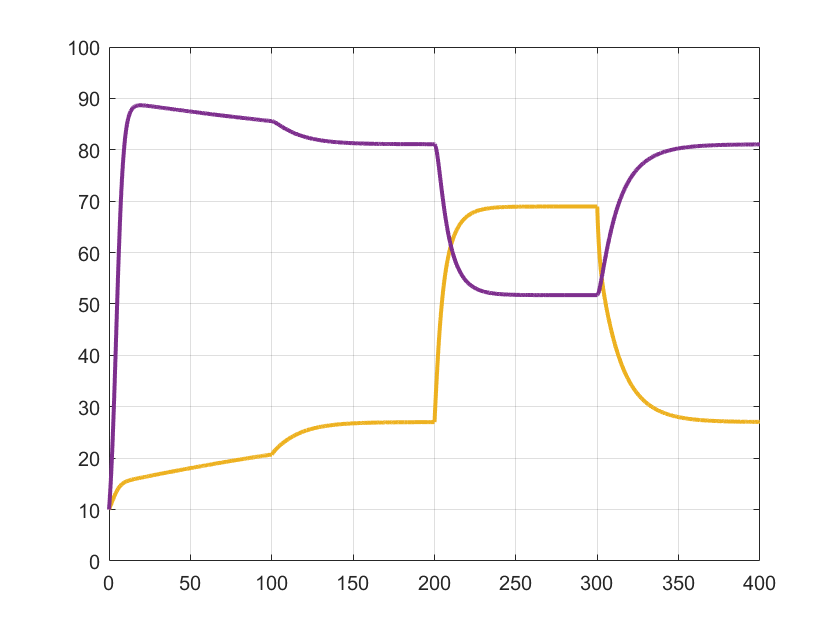

hold on;
h=0.1;%所取时间点间隔
ts1=[0:h:100];%时间区间
x01=[10,10];%初始条件

opt=odeset('reltol',1e-6,'abstol',1e-9);%相对误差1e-6，绝对误差1e-9
[t1,x1]=ode45(@fun1,ts1,x01,opt);%使用5级4阶龙格—库塔公式计算

ts2=[100:h:200];%时间区间
x02=[x1(1001,1),x1(1001,2)];%初始条件
[t2,x2]=ode45(@fun2,ts2,x02,opt);

ts3=[200:h:300];%时间区间
x03=[x2(1001,1),x2(1001,2)];%初始条件
[t3,x3]=ode45(@fun3,ts3,x03,opt);

ts4=[300:h:400];%时间区间
x04=[x3(1001,1),x3(1001,2)];%初始条件
[t4,x4]=ode45(@fun4,ts4,x04,opt);




x_2 = [x1;x2;x3;x4];


plot(t,x_2(:,1),t,x_2(:,2),'LineWidth',2);
% legend('Armillaria gallica','Merulius tremullosus'),grid on;
xlim([0,400]);
ylim([0,100]);


% plot(t1,x1(:,1),'r',t1,x1(:,2),'b','LineWidth',2);
% legend('Armillaria gallica','Merulius tremullosus'),grid on;

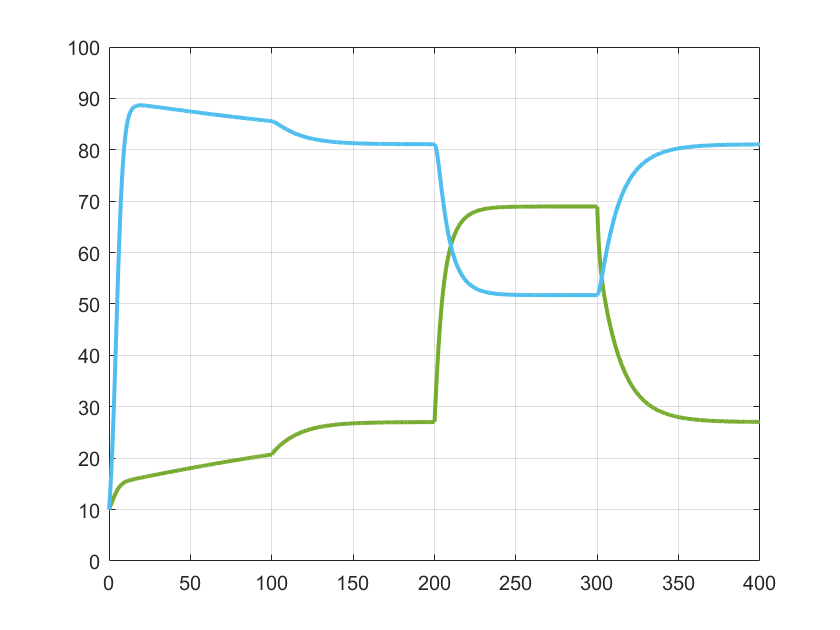

hold on;
h=0.1;%所取时间点间隔
ts1=[0:h:100];%时间区间
x01=[10,10];%初始条件

opt=odeset('reltol',1e-6,'abstol',1e-9);%相对误差1e-6，绝对误差1e-9
[t1,x1]=ode45(@fun1,ts1,x01,opt);%使用5级4阶龙格—库塔公式计算

ts2=[100:h:200];%时间区间
x02=[x1(1001,1),x1(1001,2)];%初始条件
[t2,x2]=ode45(@fun2,ts2,x02,opt);

ts3=[200:h:300];%时间区间
x03=[x2(1001,1),x2(1001,2)];%初始条件
[t3,x3]=ode45(@fun3,ts3,x03,opt);

ts4=[300:h:400];%时间区间
x04=[x3(1001,1),x3(1001,2)];%初始条件
[t4,x4]=ode45(@fun4,ts4,x04,opt);




x_3 = [x1;x2;x3;x4];


plot(t,x_3(:,1),t,x_3(:,2),'LineWidth',2);
% legend('Armillaria gallica','Merulius tremullosus'),grid on;
xlim([0,400]);
ylim([0,100]);
hold off;

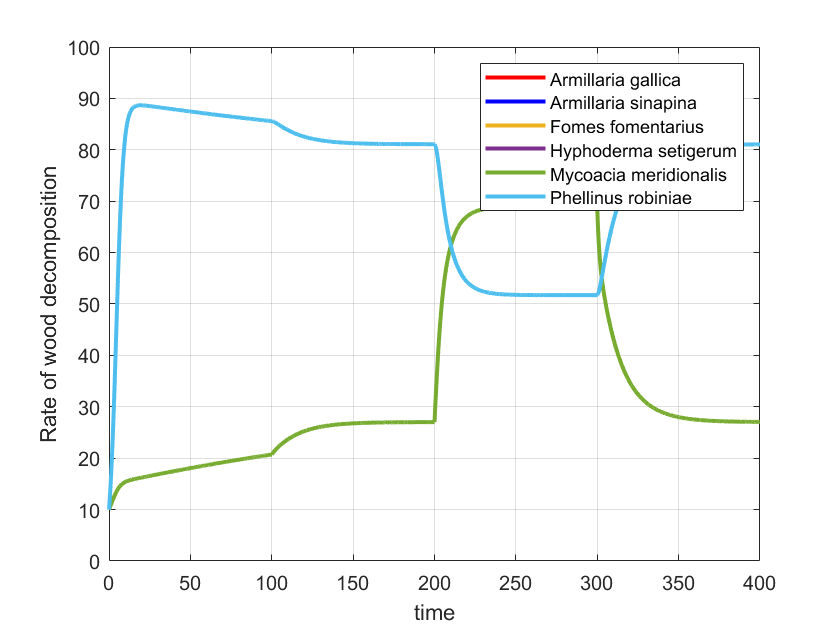

xlabel('time');
ylabel('Rate of wood decomposition');
legend('Armillaria gallica','Armillaria sinapina','Fomes fomentarius','Hyphoderma setigerum','Mycoacia meridionalis','Phellinus robiniae')

function dx=fun1(t,x,r1,r2,n1,n2,s1,s2)
    r1=.1;
    r2=0.5;
    n1=100;
    n2=100;
    s1=0.9;
    s2=0.7;
    dx=[r1*x(1)*(1-x(1)/n1-s1*x(2)/n2);r2*x(2)*(1-s2*x(1)/n1-x(2)/n2)];
end

function dx=fun2(t,x,r1,r2,n1,n2,s1,s2)
    r1=1;
    r2=.5;
    n1=100;
    n2=100;
    s1=0.9;
    s2=0.7;
    dx=[r1*x(1)*(1-x(1)/n1-s1*x(2)/n2);r2*x(2)*(1-s2*x(1)/n1-x(2)/n2)];
end

function dx=fun3(t,x,r1,r2,n1,n2,s1,s2)
    r1=1;
    r2=0.5;
    n1=100;
    n2=100;
    s1=0.6;
    s2=0.7;
    dx=[r1*x(1)*(1-x(1)/n1-s1*x(2)/n2);r2*x(2)*(1-s2*x(1)/n1-x(2)/n2)];
end

function dx=fun4(t,x,r1,r2,n1,n2,s1,s2)
    r1=1;
    r2=0.5;
    n1=100;
    n2=100;
    s1=0.9;
    s2=0.7;
    dx=[r1*x(1)*(1-x(1)/n1-s1*x(2)/n2);r2*x(2)*(1-s2*x(1)/n1-x(2)/n2)];
end